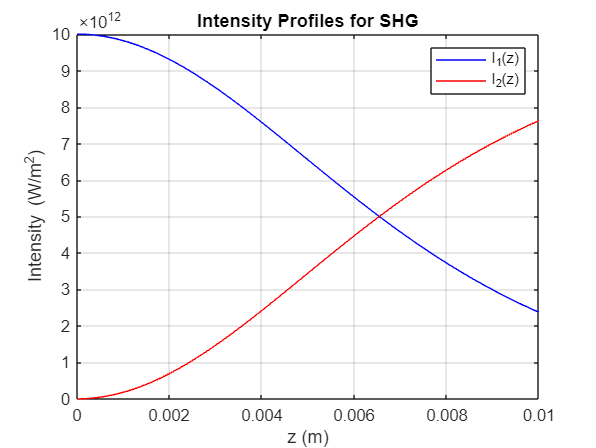

% B a


% Define parameters
lambda_1 = 1e-6;          % Wavelength in meters
n_1 = 1.6;                % Refractive index
d_eff = 1e-12;            % Nonlinear coefficient in m/V
I1_0 = 1e13;              % Initial intensity in W/m^2
epsilon_0 = 8.854e-12;    % Permittivity of free space in F/m
c = 3e8;                  % Speed of light in m/s

% Calculate omega_1, k_1, and eta
omega_1 = 2 * pi * c / lambda_1;
k_1 = 2 * pi * n_1 / lambda_1;
eta = omega_1^2 * d_eff / (k_1 * c^2);

% Initial field amplitude A1 based on intensity I1_0
A1_0 = sqrt(I1_0 / (2 * epsilon_0 * n_1 * c));
A2_0 = 0; % Initial amplitude for A2

% Define ODEs
odes = @(z, A) [1i * eta * A(2) * A(1); % dA1/dz
                1i * eta * A(1)^2];     % dA2/dz

% Solve using ode45
z_span = [0, 1e-2];      % z range from 0 to 0.01 m
A0 = [A1_0; A2_0];       % Initial conditions
[z, A] = ode45(odes, z_span, A0);

% Calculate intensity profiles
I1 = 2 * epsilon_0 * n_1 * c * abs(A(:, 1)).^2;
I2 = 2 * epsilon_0 * n_1 * c * abs(A(:, 2)).^2;

% Plot intensities
figure;
plot(z, I1, 'b', 'DisplayName', 'I_1(z)');
hold on;
plot(z, I2, 'r', 'DisplayName', 'I_2(z)');
xlabel('z (m)');
ylabel('Intensity (W/m^2)');
legend;
title('Intensity Profiles for SHG');
grid on;

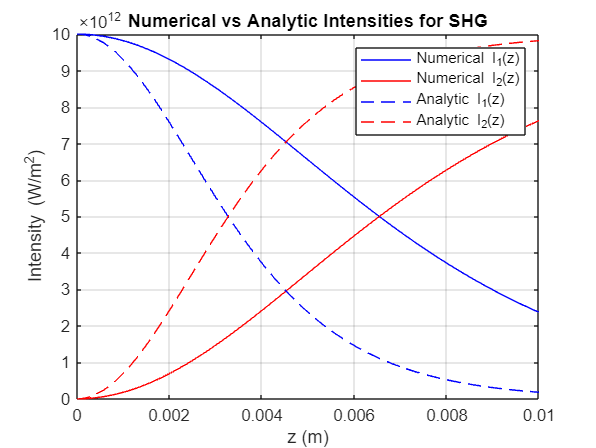

% Define parameters
lambda_1 = 1e-6;           % Wavelength in meters
n_1 = 1.6;                 % Refractive index for fundamental
n_2 = 1.6;                 % Refractive index for SH
d_eff = 1e-12;             % Nonlinear coefficient in m/V
I1_0 = 1e13;               % Initial intensity in W/m^2
epsilon_0 = 8.854e-12;     % Permittivity of free space in F/m
c = 3e8;                   % Speed of light in m/s

% Calculate omega_1, k_1, and eta
omega_1 = 2 * pi * c / lambda_1;
k_1 = 2 * pi * n_1 / lambda_1;
eta = omega_1^2 * d_eff / (k_1 * c^2);

% Initial field amplitude A1 based on intensity I1_0
A1_0 = sqrt(I1_0 / (2 * epsilon_0 * n_1 * c));
A2_0 = 0; % Initial amplitude for A2

% Effective interaction length l
ell = sqrt(2 * n_1^2 * n_2 * epsilon_0 * c^3) / (2 * omega_1 * d_eff * sqrt(I1_0));

% Define ODEs for numerical solution
odes = @(z, A) [1i * eta * A(2) * A(1); % dA1/dz
                1i * eta * A(1)^2];     % dA2/dz

% Solve ODEs numerically
z_span = [0, 1e-2];      % z range from 0 to 0.01 m
A0 = [A1_0; A2_0];       % Initial conditions
[z, A] = ode45(odes, z_span, A0);

% Numerical intensities
I1_num = 2 * epsilon_0 * n_1 * c * abs(A(:, 1)).^2;
I2_num = 2 * epsilon_0 * n_1 * c * abs(A(:, 2)).^2;

% Analytic solution
A1_analytic = A1_0 * sech(z / ell);
A2_analytic = A1_0 * tanh(z / ell);

% Analytic intensities
I1_analytic = 2 * epsilon_0 * n_1 * c * abs(A1_analytic).^2;
I2_analytic = 2 * epsilon_0 * n_1 * c * abs(A2_analytic).^2;

% Plot numerical vs analytic solutions
figure;
plot(z, I1_num, 'b', 'DisplayName', 'Numerical I_1(z)');
hold on;
plot(z, I2_num, 'r', 'DisplayName', 'Numerical I_2(z)');
plot(z, I1_analytic, 'b--', 'DisplayName', 'Analytic I_1(z)');
plot(z, I2_analytic, 'r--', 'DisplayName', 'Analytic I_2(z)');
xlabel('z (m)');
ylabel('Intensity (W/m^2)');
legend;
title('Numerical vs Analytic Intensities for SHG');
grid on;

% Parameters
lambda_1 = 1e-6;            % Wavelength in meters
n_1 = 1.6;                  % Refractive index for fundamental
n_2 = n_1;                  % Refractive index for SH (assuming same)
d_eff = 1e-12;              % Nonlinear coefficient in m/V
I1_0 = 0.1 * 1e13;          % Initial fundamental intensity in W/m^2
epsilon_0 = 8.854e-12;      % Permittivity of free space in F/m
c = 3e8;                    % Speed of light in m/s
L = 1e-2;                   % Length of the medium in meters

% Calculate angular frequency, wave number, and eta
omega_1 = 2 * pi * c / lambda_1;
k_1 = 2 * pi * n_1 / lambda_1;
eta = (omega_1^2 * d_eff) / (k_1 * c^2);

% Initial field amplitude A1 based on intensity I1_0
A1_0 = sqrt(I1_0 / (2 * epsilon_0 * n_1 * c));
A2_0 = 0; % Initial amplitude for A2

% Define phase mismatches for Delta n = 10^-4 and 3*10^-4
delta_n_values = [1e-4, 3e-4];
coherence_lengths = pi ./ (2 * omega_1 / c * delta_n_values);

% Set up figure for plotting
figure;
hold on;

% Loop through each Delta n value
for i = 1:length(delta_n_values)
    Delta_n = delta_n_values(i);
    Delta_k = 2 * omega_1 / c * Delta_n;
    
    % Define ODEs including phase mismatch term
    odes = @(z, A) [1i * eta * A(2) * A(1) * exp(-1i * Delta_k * z);  % dA1/dz
                    1i * eta * A(1)^2 * exp(1i * Delta_k * z)];       % dA2/dz

    % Solve ODEs numerically
    z_span = [0, L];
    A0 = [A1_0; A2_0];
    [z, A] = ode45(odes, z_span, A0);

    % Calculate intensities from field amplitudes
    I1 = 2 * epsilon_0 * n_1 * c * abs(A(:, 1)).^2; % Fundamental intensity
    I2 = 2 * epsilon_0 * n_1 * c * abs(A(:, 2)).^2; % SH intensity

    % Plot normalized SH intensity I2(z) / I1(0)
    plot(z, I2 / I1_0, 'DisplayName', ['\Delta n = ', num2str(Delta_n)]);
    
    % Display predicted period of Maker fringes
    fprintf('Predicted period for Delta n = %.1e: %.2e m\n', Delta_n, 2 * coherence_lengths(i));
    
    % Estimate max depletion in I1 by finding minimum value
    depletion_percentage = 100 * (1 - min(I1) / I1_0);
    fprintf('Estimated fundamental depletion for Delta n = %.1e: %.2f%%\n', Delta_n, depletion_percentage);
end

Predicted period for Delta n = 1.0e-04: 5.00e-03 m


Estimated fundamental depletion for Delta n = 1.0e-04: 0.48%


Predicted period for Delta n = 3.0e-04: 1.67e-03 m


Estimated fundamental depletion for Delta n = 3.0e-04: 0.05%


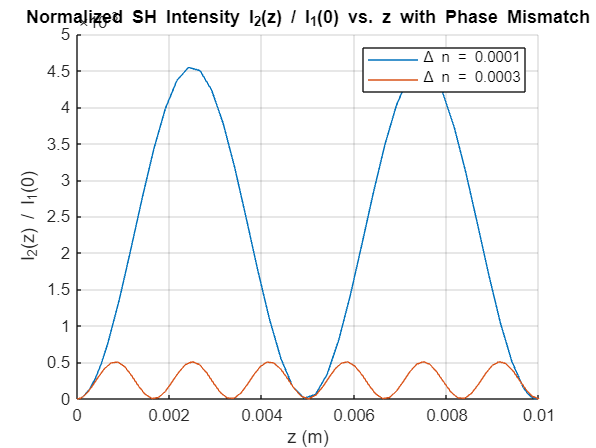


% Customize plot
xlabel('z (m)');
ylabel('I_2(z) / I_1(0)');
title('Normalized SH Intensity I_2(z) / I_1(0) vs. z with Phase Mismatch');
legend;
grid on;

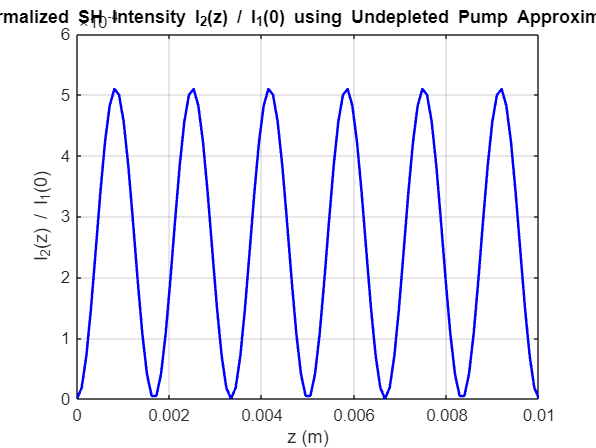

% Parameters
lambda_1 = 1e-6;            % Wavelength in meters
n_1 = 1.6;                  % Refractive index for fundamental
d_eff = 1e-12;              % Nonlinear coefficient in m/V
I1_0 = 0.1 * 1e13;          % Initial fundamental intensity in W/m^2
epsilon_0 = 8.854e-12;      % Permittivity of free space in F/m
c = 3e8;                    % Speed of light in m/s
L = 1e-2;                   % Length of the medium in meters

% Calculate angular frequency, wave number, and eta
omega_1 = 2 * pi * c / lambda_1;
k_1 = 2 * pi * n_1 / lambda_1;
eta = (omega_1^2 * d_eff) / (k_1 * c^2);

% Initial field amplitude A1 based on intensity I1_0
A1_0 = sqrt(I1_0 / (2 * epsilon_0 * n_1 * c));

% Phase mismatch for Delta n = 3*10^-4
Delta_n = 3e-4;
Delta_k = 2 * omega_1 / c * Delta_n;

% Define the function to evaluate the integral
A2_integral = @(z) eta * A1_0^2 * integral(@(z_prime) exp(1i * Delta_k * z_prime), 0, z, 'ArrayValued', true);

% Define z values for plotting
z_values = linspace(0, L, 100);

% Initialize array to store I2 values
I2_values = zeros(size(z_values));

% Compute I2(z) at each z value using the undepleted pump approximation
for i = 1:length(z_values)
    z = z_values(i);
    A2_z = A2_integral(z);  % Evaluate the integral to find A2(z)
    I2_values(i) = 2 * epsilon_0 * n_1 * c * abs(A2_z)^2;  % SH intensity I2(z)
end

% Plot the normalized SH intensity I2(z) / I1(0)
figure;
plot(z_values, I2_values / I1_0, 'b-', 'LineWidth', 1.5);
xlabel('z (m)');
ylabel('I_2(z) / I_1(0)');
title('Normalized SH Intensity I_2(z) / I_1(0) using Undepleted Pump Approximation');
grid on;

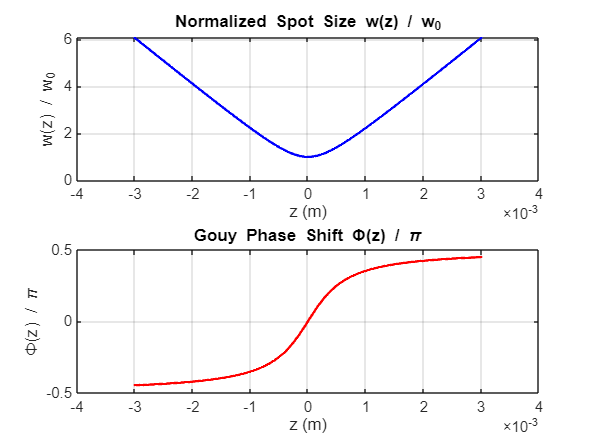

% C b

% Given parameters
lambda_1 = 1e-6;           % Wavelength in meters
n_1 = 1.6;                 % Refractive index
w_0 = 10e-6;               % Spot size at focus in meters

% Calculate k1 and confocal parameter b
k_1 = 2 * pi * n_1 / lambda_1;
b = k_1 * w_0^2;

% Define z range for plotting
z = linspace(-3*b, 3*b, 1000);

% Calculate w(z)/w_0 and Phi(z)/pi
w_z = w_0 * sqrt(1 + (2*z/b).^2);
Phi_z = atan(2*z/b);

% Plot w(z)/w_0
figure;
subplot(2, 1, 1);
plot(z, w_z / w_0, 'b-', 'LineWidth', 1.5);
xlabel('z (m)');
ylabel('w(z) / w_0');
title('Normalized Spot Size w(z) / w_0');
grid on;

% Plot Phi(z)/pi
subplot(2, 1, 2);
plot(z, Phi_z / pi, 'r-', 'LineWidth', 1.5);
xlabel('z (m)');
ylabel('\Phi(z) / \pi');
title('Gouy Phase Shift \Phi(z) / \pi');
grid on;

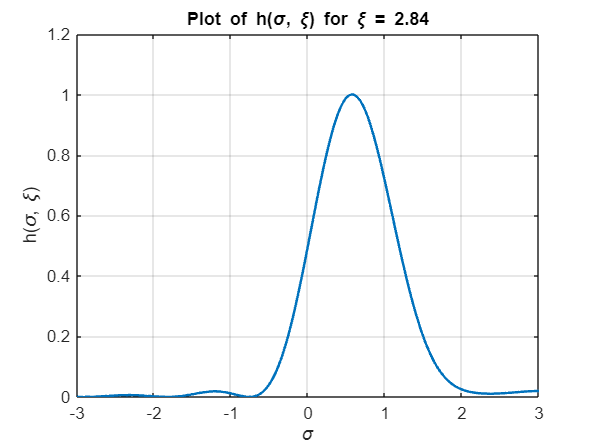

% II A b

% Parameters
xi = 2.84;                           % Focusing parameter
sigma_range = linspace(-3, 3, 500);  % Range of sigma values for plotting

% Define the integrand function for J_q (zeta integrand for h(sigma, xi))
J2_integrand = @(sigma, zeta) exp(1i * sigma * zeta) ./ (1 + 1i * zeta);

% Initialize array to store h(sigma, xi) values
h_values = zeros(size(sigma_range));

% Loop through sigma values and calculate h(sigma, xi) for each
for i = 1:length(sigma_range)
    sigma = sigma_range(i);
    
    % Compute the integral |J2|^2 using MATLAB's integral function
    integral_value = integral(@(zeta) J2_integrand(sigma, zeta), -xi, xi, 'ArrayValued', true);
    h_values(i) = abs(integral_value)^2 / (4.27 * xi);
end

% Plot h(sigma, xi) versus sigma
figure;
plot(sigma_range, h_values, 'LineWidth', 1.5);
xlabel('\sigma');
ylabel('h(\sigma, \xi)');
title(['Plot of h(\sigma, \xi) for \xi = ', num2str(xi)]);
grid on;

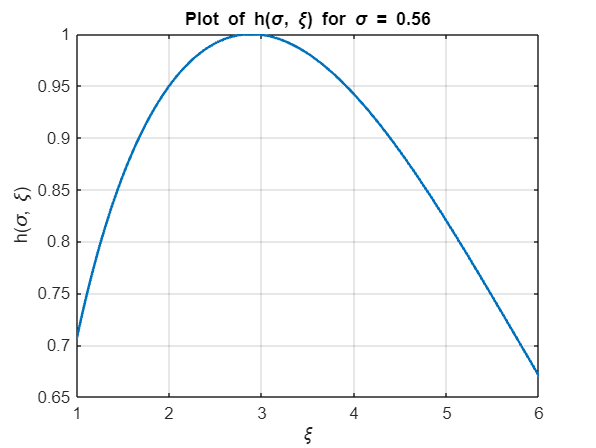

% II A c

% Parameters for part (c)
sigma_fixed = 0.56;                % Fixed phase-mismatch parameter
xi_range = linspace(1, 6, 500);    % Range of xi values for plotting

% Define the integrand function for J_q (zeta integrand for h(sigma, xi))
J2_integrand = @(xi, zeta) exp(1i * sigma_fixed * zeta) ./ (1 + 1i * zeta);

% Initialize array to store h(sigma, xi) values for varying xi
h_values = zeros(size(xi_range));

% Loop through xi values and calculate h(sigma, xi) for each
for j = 1:length(xi_range)
    xi = xi_range(j);
    
    % Compute the integral |J2|^2 using MATLAB's integral function
    integral_value = integral(@(zeta) J2_integrand(xi, zeta), -xi, xi, 'ArrayValued', true);
    h_values(j) = abs(integral_value)^2 / (4.27 * xi);
end

% Plot h(sigma, xi) versus xi
figure;
plot(xi_range, h_values, 'LineWidth', 1.5);
xlabel('\xi');
ylabel('h(\sigma, \xi)');
title(['Plot of h(\sigma, \xi) for \sigma = ', num2str(sigma_fixed)]);
grid on;

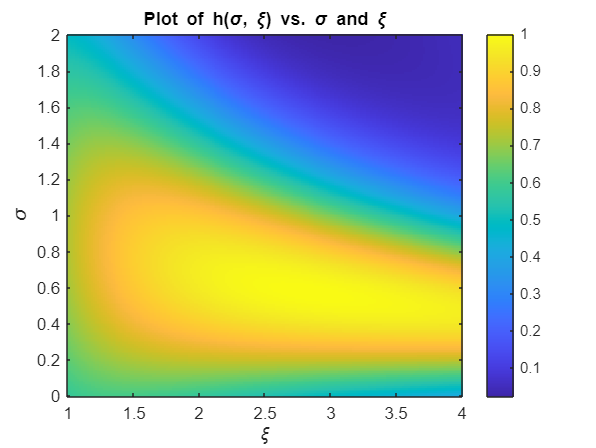

% II A d

% Parameters for part (d)
xi_range = linspace(1, 4, 200);       % Range of xi values
sigma_range = linspace(0, 2, 200);    % Range of sigma values

% Initialize a matrix to store h(sigma, xi) values
h_matrix = zeros(length(sigma_range), length(xi_range));

% Loop through values of sigma and xi to calculate h(sigma, xi)
for i = 1:length(sigma_range)
    sigma = sigma_range(i);
    for j = 1:length(xi_range)
        xi = xi_range(j);
        
        % Define the integrand for J_2 as a function of zeta with the current sigma
        J2_integrand = @(zeta) exp(1i * sigma * zeta) ./ (1 + 1i * zeta);
        
        % Compute |J2|^2 using MATLAB's integral function
        integral_value = integral(@(zeta) J2_integrand(zeta), -xi, xi, 'ArrayValued', true);
        h_matrix(i, j) = abs(integral_value)^2 / (4.27 * xi);
    end
end

% Plot using imagesc
figure;
imagesc(xi_range, sigma_range, h_matrix);
xlabel('\xi');
ylabel('\sigma');
title('Plot of h(\sigma, \xi) vs. \sigma and \xi');
colorbar;
axis xy;  % Flip y-axis for correct display orientation

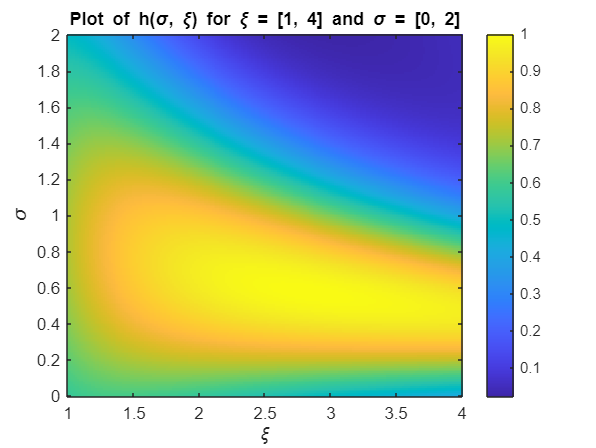

% Define the ranges for xi and sigma
xi_range = linspace(1, 4, 200);       % Focusing parameter range
sigma_range = linspace(0, 2, 200);    % Phase mismatch parameter range

% Initialize a 2D array to store h(sigma, xi) values
h_values = zeros(length(sigma_range), length(xi_range));

% Loop over each pair of sigma and xi values
for i = 1:length(sigma_range)
    sigma = sigma_range(i);  % Current sigma value
    
    % Nested loop over xi values
    for j = 1:length(xi_range)
        xi = xi_range(j);  % Current xi value
        
        % Define the integrand function for J_q(zeta) with given sigma and xi
        J2_integrand = @(zeta) exp(1i * sigma * zeta) ./ (1 + 1i * zeta);
        
        % Compute the integral |J2|^2 for the current sigma and xi
        integral_value = integral(@(zeta) J2_integrand(zeta), -xi, xi, 'ArrayValued', true);
        
        % Store the result in h_values for current sigma and xi
        h_values(i, j) = abs(integral_value)^2 / (4.27 * xi);
    end
end

% Plot the results using imagesc
figure;
imagesc(xi_range, sigma_range, h_values);
colorbar;
xlabel('\xi');
ylabel('\sigma');
title('Plot of h(\sigma, \xi) for \xi = [1, 4] and \sigma = [0, 2]');
set(gca, 'YDir', 'normal');  % Correct orientation for sigma axis

% Given parameters
L = 3e-3;             % Length of the nonlinear medium in meters
lambda = 1.064e-6;    % Fundamental wavelength (in meters, typical for Nd:YAG laser)
k1 = 2 * pi / lambda; % Wavenumber of the fundamental beam

% Optimal values from previous simulations
xi_optimal = 2.84;    % Optimal focusing parameter found earlier
sigma_optimal = 0.56; % Optimal phase-mismatch parameter found earlier

% Calculate the required confocal parameter b from xi = L/b
b_optimal = L / xi_optimal;

% Solve for the required spot size w0
w0_optimal = sqrt(b_optimal / k1);

% Calculate the required refractive index difference Delta_n for optimal sigma
Delta_n_optimal = (2 * sigma_optimal * lambda) / (b_optimal * 2 * pi);

% Display results
fprintf('Optimal spot size (w0) at medium entrance: %.2e meters\n', w0_optimal);

Optimal spot size (w0) at medium entrance: 1.34e-05 meters


fprintf('Optimal refractive-index difference (n1 - n2): %.2e\n', Delta_n_optimal);

Optimal refractive-index difference (n1 - n2): 1.80e-04


% Given constants
d_eff = 15e-12;               % Effective nonlinear coefficient in m/V
epsilon_0 = 8.85e-12;         % Vacuum permittivity in F/m
n1 = 1.6;                     % Refractive index for the fundamental field
n2 = n1;                      % Assuming n2 ~ n1
c = 3e8;                      % Speed of light in m/s
w0_optimal = 1.5e-6;          % Spot size (from part e, as an example)

% Fundamental parameters
P1 = 10;                      % Fundamental input power in watts
h_sigma_xi = 0.25;            % Approximate geometric factor based on previous plot

% Calculate K using the given parameters
K = (2.14 * w0_optimal^2 * d_eff^2) / (epsilon_0 * n1^2 * n2 * c^3 * pi);

% Calculate E_NL
E_NL = K * h_sigma_xi;

% Calculate SH output power P2
P2 = E_NL * P1^2;

% Display the results
fprintf('Nonlinear efficiency factor (E_NL): %.2e W^-1\n', E_NL);

Nonlinear efficiency factor (E_NL): 8.81e-50 W^-1


fprintf('Second harmonic output power (P2) for P1 = 10 W: %.2f W\n', P2);

Second harmonic output power (P2) for P1 = 10 W: 0.00 W
